# Aufgabe 3 (Pulsbreite eines Femtosekundenlasers)

(weitere Erklärungen zum Hintergrund dieser Aufgabe gibt’s vor Ort beim Praktikum.)

Femtosekundenlaser erzeugen Lichtpulse, die nur wenige Femtosekunden dauern (1 Femtosekunde =${10}^{-15}$ Sekunden) und haben viele Anwendungen in Wissenschaft und Technik. Um die Form eines solchen Lichtpulses genauer zu bestimmen, wird oft die *FROG*-Technik genutzt, bei der die Autokorrelation des Lichtpulses im Frequenzbereich gemessen wird. Im Ordner `Daten/FrogTraces` befindet sich eine Sammlung sogenannter *Frog*-Traces. Dabei handelt es sich um Spektrogramme der Autokorrelation von kurzen Laserpulsen.

Der interessierte Leser findet hier weitere Informationen: [https://uol.de/f/5/inst/physik/ag/ukd/Publikationen/2007/Skript-Version30.pdf.](https://uol.de/f/5/inst/physik/ag/ukd/Publikationen/2007/Skript-Version30.pdf.) Ab Seite 70 werden die Frog-Traces für einige Pulsformen dargestellt. 

In dieser Aufgabe geht es darum, ein vollverbundenes Netz zu entwickeln, das die Pulsbreite anhand des Spektrogramms des Pulses vorhersagt. Die Pulsbreite für jedes Spektrogramm ist in den Dateien `MetaDataTrain.csv` und `MetaDataTest.csv `gegeben.

### Aufgabe 3 (a) Daten laden

Laden Sie die Trainingsdaten und bringen Sie sie in eine für vollverbundene Netze geeignete Form.

dataDir = fullfile('Daten', 'FrogTraces'); 
trainDir = fullfile(dataDir, 'train');
testDir = fullfile(dataDir, 'test');
metaDataTrain = readtable(fullfile(trainDir, 'MetaDataTrain.csv'));
metaDataTest = readtable(fullfile(testDir, 'MetaDataTest.csv'));
nTrain = size(metaDataTrain, 1);
nTest = size(metaDataTest, 1);

Ein Bild laden und ansehen:

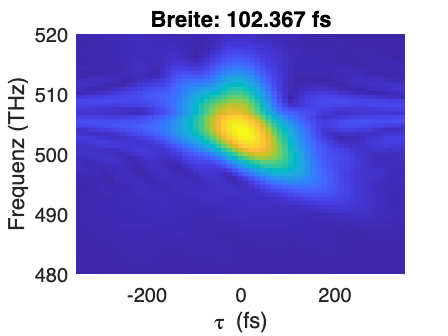

img = imread(fullfile(trainDir, [metaDataTrain.Name{1} '.png']));
imSize = size(img);
pc = pcolor(linspace(-350, 350, imSize(1)), ...
   linspace(480, 520, imSize(2)), img);
pc.LineStyle='none';
title(sprintf('Breite: %.3f fs', metaDataTrain.RMSWidth(1)));
xlabel('\tau (fs)');
ylabel('Frequenz (THz)');

Trainingsdaten einlesen:

P = imSize(1)*imSize(2);  % Anzahl Pixel (= Merkmale)
trainMat = zeros(nTrain, P);

for i = 1:nTrain
   img = imread(fullfile(trainDir, [metaDataTrain.Name{i} '.png']));
   % img in die i-te Zeile schreiben von trainMat schreiben:
   trainMat(i, :) = reshape(img, 1, []);
   % TODO: ab hier weiter machen!
end
% Zielgroessen aus Tabelle holen:
trainTarget = metaDataTrain.RMSWidth;
trainMat

trainMat =      0     0     0     0     0     1     1     1     1     1     1     1     1     2     2     2     2     1     2     2     2     1     2     3     3     6     9     8     8    12    12    11    17    22    13    11    27    34    25    16    18    27    27    17     3     7    11     8     2     2
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     2     2     3     5     5     8    13    18    22    24    22    18    17    24    35    46    54    57    55    48    38    27    17    10     5     2     0     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     2     2     4     7    10    13    18    24    30    38    44    51    56    61    64    65    65    63    59    54    47    40    33    26    20    15    11     8     5     3     2     1     1
     0     0     1     1     1     1     1     2     2     2     3     4     4     6  

% histogram(trainTarget);

### Aufgabe 3 (b) Vollverbundes Netz entwerfen

Entwickeln Sie ein vollverbundenes, neuronales Netz, das die Pulsbreite möglichst gut vorhersagt.

H = 90;
lambda = 0;
options = trainingOptions('adam',...
   'ValidationData', {abs(trainMat), trainTarget}, ...
   'MaxEpochs', 150, ...
   'MinibatchSize', 300, ...
   'L2Regularization', lambda, ...
   'Verbose', true, ...
   'Plots', 'none'); % training-progress'); 

layers = [featureInputLayer(P)
    batchNormalizationLayer
   fullyConnectedLayer(H)
   reluLayer
   fullyConnectedLayer(H)
   reluLayer
   fullyConnectedLayer(1)
   regressionLayer];
tic
net = trainNetwork(abs(trainMat), trainTarget, layers, options);

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |        97.99 |       100.45 |    4801.4634 |    5045.0708 |          0.0010 |
|      10 |          50 |       00:00:01 |        97.66 |        97.63 |    4769.0439 |    4765.8447 |          0.0010 |
|      20 |         100 |       00:00:03 |        95.61 |        95.53 |    4570.4023 |    4563.2822 |          0.0010 |
|      30 |         150 |       00:00:04 |        93.31 |        93.21 |    4353.4531 |    4344.3286 |          0.0010 |
|      4

toc

Elapsed time is 22.657049 seconds.


### Aufgabe 3 (c) Anwenden auf Testdaten 

Laden Sie die Testdaten und überprüfen Sie damit die Qualität Ihres in Teil (b) entwickelten Netzes.

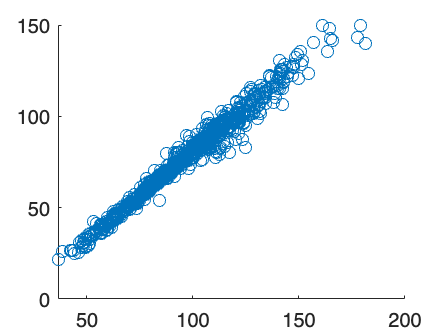

testMat = zeros(nTest, P);

for i = 1:nTest
   img = imread(fullfile(testDir, [metaDataTest.Name{i} '.png']));
   % img in die i-te Zeile schreiben von trainMat schreiben:
   testMat(i, :) = reshape(img, 1, []);
   % TODO: ab hier weiter machen!
end
% Zielgroessen aus Tabelle holen:
testTarget = metaDataTest.RMSWidth;
% histogram(trainTarget);

testPred = predict(net, testMat);

scatter(testTarget, testPred);


RMSETest = sqrt(1/nTest * sum( (testTarget - testPred).^2 ))

RMSETest = single
19.8040